## Conexión con el Robot.

Se busca en las conexiones USB y se espera el comando.

Robot = ArduinoManager();
 

## Inicialización.

Moviendo los servos a 90º

Robot.setServos(0, 0);
 

## Posiciones nuevas

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

P1 = 90
P2 = -90

## Enviar comando

Robot.setServos(P1, P2);
[x, y] = cinem_directa_analitica(P1, P2)
[xd, yd] = cinematica_DH(P1, P2)
 

## Actualización continua

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

P1 = -9;
P2 = -21;
Robot.setServos(P1, P2);
[x, y] = cinem_directa_analitica(P1, P2)
[xd, yd] = cinematica_DH(P1, P2)
 

## Cinemática directa y espacio de trabajo

EspacioDeTrabajo(8.75, 11);
 

## Uso de la cinemática inversa

Introduce las coordenadas X, Y deseadas. 

Asegurate que pertenezcan al espacio de trabajo!

X = 25        

X = 25

Y = 0

Y = 0

[P1, P2] = ik_geometrica(X, Y)

P1 = -33.8078

P2 = 54.9097

Robot.setServos(P1, P2);
 

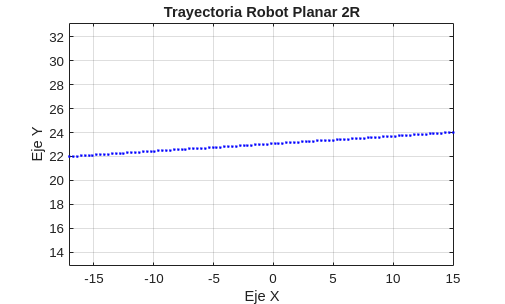

qMatrix =        NaN       NaN   25.8862   20.7959   17.2652   14.3275   11.7295    9.3593    7.1555    5.0802    3.1080    1.2211   -0.5936   -2.3463   -4.0445   -5.6947   -7.3017   -8.8695  -10.4017  -11.9010  -13.3697  -14.8099  -16.2232  -17.6111  -18.9747  -20.3152  -21.6332  -22.9297  -24.2051  -25.4600  -26.6948  -27.9098  -29.1053  -30.2814  -31.4383  -32.5761  -33.6947  -34.7942  -35.8745  -36.9356  -37.9772  -38.9993  -40.0017  -40.9841  -41.9464  -42.8883  -43.8096  -44.7100  -45.5892  -46.4469
       NaN       NaN    8.2962   15.7581   20.6325   24.5135   27.8188   30.7336   33.3592   35.7586   37.9736   40.0340   41.9616   43.7732   45.4818   47.0979   48.6298   50.0846   51.4681   52.7851   54.0398   55.2357   56.3760   57.4633   58.4999   59.4878   60.4289   61.3246   62.1764   62.9855   63.7530   64.4798   65.1669   65.8149   66.4247   66.9967   67.5315   68.0296   68.4914   68.9173   69.3076   69.6627   69.9828   70.2681   70.5187   70.7350   70.9170   71.0648   71.178

qMatrix = TrayectoriaCartesiana([24, 15], [22, -17])

Robot.ejecutarTrayectoria(qMatrix, 2)

numPasos = 100

Trayectoria finalizada.
